grayImage = imread('cameraman.tif');

imfinfo("cameraman.tif")

ans = struct with fields:
                     Filename: 'D:\Amrita\Teaching\Odd_Sem_July_Dec2021\15EEE337_Digital Image Processing\Codes\matlab_code\cameraman.tif'
                  FileModDate: '25-Jul-2021 22:41:42'
                     FileSize: 65240
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [77 77 0 42]
                    ByteOrder: 'big-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 8262 16426 24578 32492 40499 48599 56637]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [8254 8164 8152 7914 8007 8100 8038 8235]
                  XResolution: 72
                  YResolution: 72
  

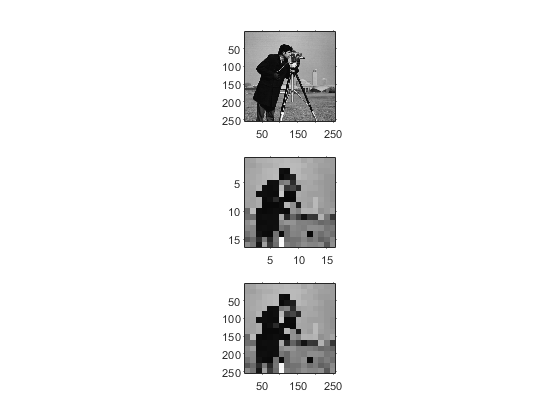


subplot(3,1,1);
imshow(grayImage);
axis on;

smallImage = imresize(grayImage, 1/16, 'nearest');
subplot(3,1,2);
imshow(smallImage);
axis on;

bigImage = imresize(smallImage, 16, 'nearest');
subplot(3,1,3);
imshow(bigImage);
axis on;